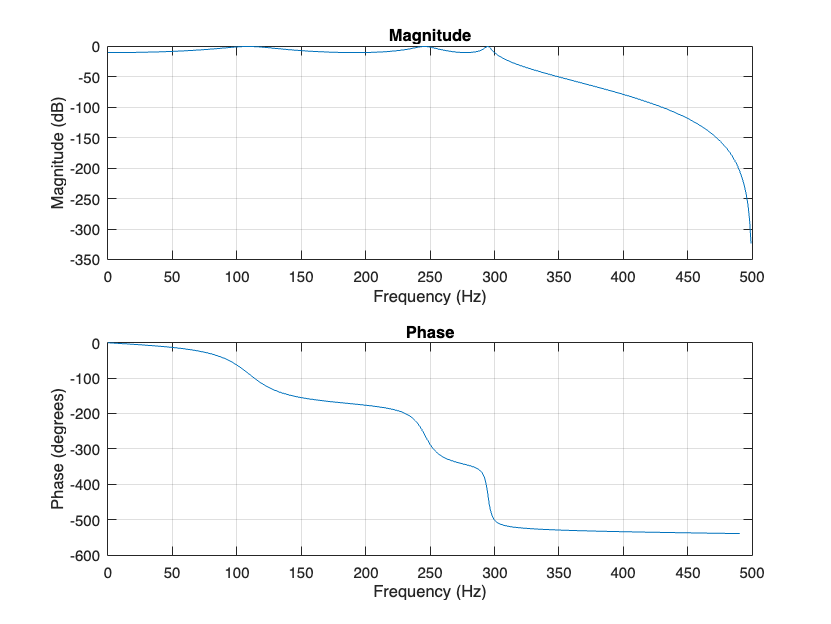

fc = 300;
fs = 1000;

[b,a] = cheby1(6,10,fc/(fs/2));

freqz(b,a,[],fs)

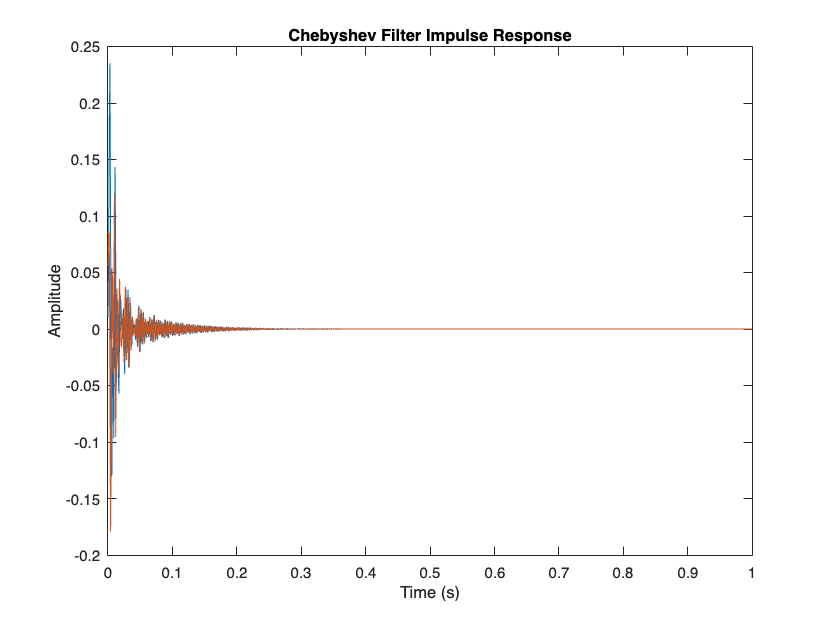


% Compute and plot filter impulse response
impulse_response = filter(b, a, [1, zeros(1, fs-1)]);
ird = gradient(impulse_response);
t = 0:1/fs:1-1/fs;
figure
plot(t, impulse_response);
hold on
plot(t, ird);
xlabel('Time (s)');
ylabel('Amplitude');
title('Chebyshev Filter Impulse Response');